outDir = 'transport';
if ~exist(outDir,'dir'); mkdir(outDir); end

Lx = 150;
Ly = 50;
visc = 1e-3;
pinlet = 1e5;
poutlet = 0;
tol = 1e-12;
seed = NaN;
num_trials = 1000; % number of networks for each (discspacing, lx, ly, b)
num_param_sets = 5; % 10000
weights = rand(num_param_sets, 3) % 3 = number of parameters -- can be changed to only be in the for loop

weights =     0.4953    0.0089    0.6391
    0.6112    0.8605    0.0558
    0.2527    0.7160    0.1567
    0.8819    0.4722    0.2682
    0.1064    0.0223    0.8059



discspacing = 0.1 % 5

discspacing = 0.1000

b = 0.01e-3 % 0.3e-3

b = 1.0000e-05

length_ratio = 0.5 %, 0.5

length_ratio = 0.5000


lx = length_ratio*Lx

lx = 75

ly = length_ratio*Ly

ly = 25

Nx = round(Lx/discspacing)

Nx = 1500

Ny = round(Ly/discspacing)

Ny = 500

   
bmin = b;
bmax = b;

run_trial(Lx,Ly,Nx,Ny,lx,ly,bmin,bmax,visc,pinlet,poutlet,tol,seed)

ans = logical
   1


% [xfmid,xfini,xfend,yfmid,yfini,yfend,lfx,lfy,bfx,bfy,seed] = ...
%     generate_fractures(Lx,Ly,Nx,Ny,lx,ly,bmin,bmax,seed);
% [posnode,nfracx,nfracy,nnode] = ...
%     fracture_intersections(Lx,Ly,Nx,Ny,xfmid,xfini,xfend,yfmid,yfini,yfend);
% [linknods,linkapert,linktrans,nlink] = ...
%     build_network(nnode,posnode,nfracx,nfracy,Nx,Ny,bfx,bfy,visc);
% [Adjmat,backbonenods,isolatednods,inletnods,outletnods] = ...
%     backbone(linknods,linktrans,posnode,nnode,Lx);
% [conninletnods,connoutletnods,pvec] = ...
%     solve_flow(Adjmat,backbonenods,isolatednods,inletnods,outletnods,pinlet,poutlet);
% [linkflow,linkvel,conninletlinks,flow_in] = ...
%     flow_velocity(linktrans,linkapert,linknods,backbonenods,isolatednods,...
%     conninletnods,connoutletnods,pvec,tol);
[linktrans,linkapert,linknods,backbonenods,isolatednods,...
        conninletnods,connoutletnods,pvec,tol,linkflow,linkvel,conninletlinks,flow_in] = run_trial_detailed(Lx, Ly, Nx, Ny, lx, ly, bmin, bmax, visc, pinlet, poutlet, tol, seed)

linktrans = 1.0e-09 *

    0.0000
    0.0000
    0.0000
    0.0001
    0.0001
    0.0000
    0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001


linkapert = 1.0e-05 *

    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


linknods =      1     2
     2     3
     3     4
     4     5
     5     6
     6     7
     7     8
     8     9
     9    10
    10    11
    12    13
    13    14
    14    15
    15    16
    16    17


backbonenods =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15



isolatednods =

  0×1 empty double column vector



conninletnods =          320
         470
         693
        1134
        1151
        1178
        1466
        1606
        1739
        1863
        1872
        1995
        2104
        2569
        2752


connoutletnods =     53
    56
   145
   159
   259
   269
   279
   362
   372
   382
   524
   535
   655
   666
   811


pvec = 1.0e+05 *

    0.8870
    0.8762
    0.8450
    0.8347
    0.8310
    0.8233
    0.7857
    0.7803
    0.7581
    0.7395
    0.7301
    0.9471
    0.8871
    0.8762
    0.8449


tol = 1.0000e-12

linkflow = 1.0e-09 *

    0.0470
    0.0552
    0.0457
    0.0451
    0.0453
    0.0506
    0.0487
    0.0463
    0.0438
    0.0397
    0.0690
    0.0473
    0.0553
    0.0456
    0.0451


linkvel = 1.0e-04 *

    0.0470
    0.0552
    0.0457
    0.0451
    0.0453
    0.0506
    0.0487
    0.0463
    0.0438
    0.0397
    0.0690
    0.0473
    0.0553
    0.0456
    0.0451


conninletlinks =          295
         434
         640
        1054
        1069
        1095
        1368
        1499
        1623
        1741
        1749
        1865
        1966
        2409
        2585


flow_in = 1.7110e-08

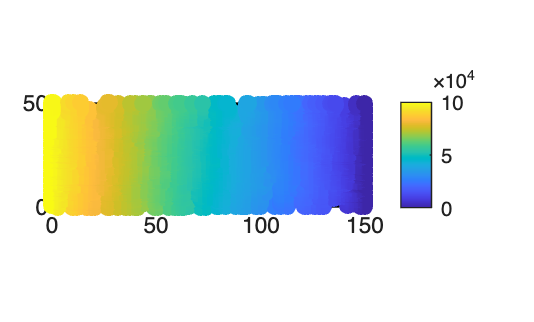


% plot_flow(2,Lx,Ly,linkflow,linknods,backbonenods,posnode,pvec,tol)
% save_figure(2,'transport', 'flow_diagram')

Np = 1000;

Np = 100

timeout = 999999;

timeout = 999999

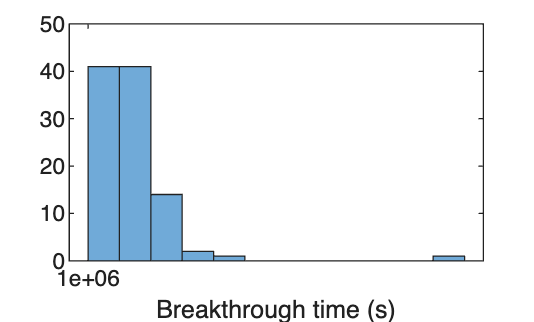


[npaths,tpaths] = ...
    simul_transport(linkflow,linkvel,linknods,posnode,...
    conninletnods,conninletlinks,connoutletnods,tol,Np, timeout);
plot_bkt(5,tpaths)
save_figure(5,'transport', 'breakthrough_histogram')

breakthrough_times = cellfun(@(t) t(end), tpaths);

min = min(breakthrough_times)

Array indices must be positive integers or logical values.

min appears to be both a function and a variable. If this is unintentional, use 'clear min' to remove the variable 'min' from the workspace.

med = median(breakthrough_times)
max = max(breakthrough_times)

% paramset_idx = 0
% num_trials = 1
% mytable = table( ...
%     repmat(discspacing, num_trials, 1), ...
%     repmat(length_ratio,num_trials, 1), ...
%     repmat(b,           num_trials, 1), ...
%     mins, ...
%     medians,...
%     maxes,...
%     'VariableNames', {'discspacing','length_ratio','b','min(breakthrough)', 'median(breakthrough)', 'max(breakthrough)'} ...
% );
% 
% filename = "tranposrt_outputs_" + paramset_idx + ".csv";
% writetable(tables{paramset_idx}, filename);

% compute global log10 x-axis limits across all param sets and all three stats
all_vals = [cell2mat(all_min_bkt); cell2mat(all_median_bkt); cell2mat(all_max_bkt)];
finite_vals = all_vals(isfinite(all_vals) & all_vals > 0);
xmin_log = floor(log10(min(finite_vals)));
xmax_log = ceil(log10(max(finite_vals)));
tick_vals = xmin_log:xmax_log;

for paramset_idx = 1:num_param_sets
    fig = figure(2); clf;
    subtitles = {"Min BKT", "Median BKT", "Max BKT"};
    data = {all_min_bkt{paramset_idx}, all_median_bkt{paramset_idx}, all_max_bkt{paramset_idx}};
    for k = 1:3
        subplot(1, 3, k);
        vals = data{k};
        finite_v = vals(isfinite(vals) & vals > 0);
        if ~isempty(finite_v)
            histogram(log10(finite_v), 'BinLimits', [xmin_log, xmax_log]);
        end
        xlim([xmin_log, xmax_log]);
        set(gca, 'XTick', tick_vals, ...
            'XTickLabel', arrayfun(@(x) sprintf('10^{%d}', x), tick_vals, 'UniformOutput', false));
        xlabel('Breakthrough time (s)');
        title(subtitles{k});
    end
    sgtitle("Param set " + paramset_idx);
    set(fig, 'PaperUnits', 'inches', 'PaperPosition', [0.5 0.5 10 3]);
    print(fig, '-dpdf', '-loose', fullfile(outDir, char("bkt_dist_" + paramset_idx + ".pdf")));
end